# Example: MHKiT-MATLAB WEC-Sim

This example loads simulated data from a [WEC-Sim](http://wec-sim.github.io/WEC-Sim/index.html) run for a two-body point absorber [(Reference Model 3)](http://wec-sim.github.io/WEC-Sim/tutorials.html#two-body-point-absorber-rm3) and demonstrates the application of the [MHKiT wave module](https://mhkit-software.github.io/MHKiT/mhkit-python/api.wave.html) to interact with the simulated data. The analysis is broken down into  three parts: load WEC-Sim data, view and interact with the WEC-Sim data , and apply the MHKiT wave module.

- Load WEC-Sim Simulated Data

- WEC-Sim Simulated Data

- Apply MHKiT Wave Module

- Wave Class Data

- Body Class Data

- PTO Class Data

- Constraint Class Data

- Mooring Class Data

## 1. Load WEC-Sim Simulated Data

WEC-Sim saves output data as a MATLAB output object, generated by WEC-Sim’s [Response Class](http://wec-sim.github.io/WEC-Sim/api.html#response-class). The WEC-Sim output object must be converted to a structure for use in Python.

Here we will load the WEC-Sim RM3 data run with a mooring matrix.

filename = '.\data\RM3MooringMatrix_matlabWorkspace.mat'

filename = '.\data\RM3MooringMatrix_matlabWorkspace.mat'

load(filename,'output')

**NOTE:** The `mhkit.wave.io.wecsim.read_output` function prints a message letting the user know which WEC-Sim classes  were not used. This WEC-Sim example data for the RM3 was not run with  MoorDyn or PTO-Sim.

**NOTE**: Conversion of the WEC-Sim object to a struct must be done *in MATLAB* and can be achieved using the command: `output` `=` `struct(output);`.

## 2. WEC-Sim Simulated Data

This section will investigate the WEC-Sim RM3 data loaded using MHKiT. In the previous section `mhkit.wave.io.wecsim.read_output` returned a [dictonary](https://docs.python.org/3/tutorial/datastructures.html#dictionaries) of [DataFrames](https://pandas.pydata.org/pandas-docs/stable/user_guide/dsintro.html#dataframe) in a format similar to the WEC-Sim output object. To see what data is available we can call the `keys` method on the `wecsim_data` dictionary:

### **Wave Class Data**

Data from WEC-Sim’s [Wave Class](http://wec-sim.github.io/WEC-Sim/code_structure.html#wave-class) includes information about the wave input, including the the wave type, and wave elevation as a function of time. Below we will wave the wave  DataFrame as wave and then look at the wave type and the top (head) of  the DataFrame.

% Store WEC-Sim output from the Wave Class to a new dataFrame, called `wave_data`
wave_data = output.wave

wave_data = struct with fields:
         type: 'etaImport'
         time: [40001×1 double]
    elevation: [40001×1 double]


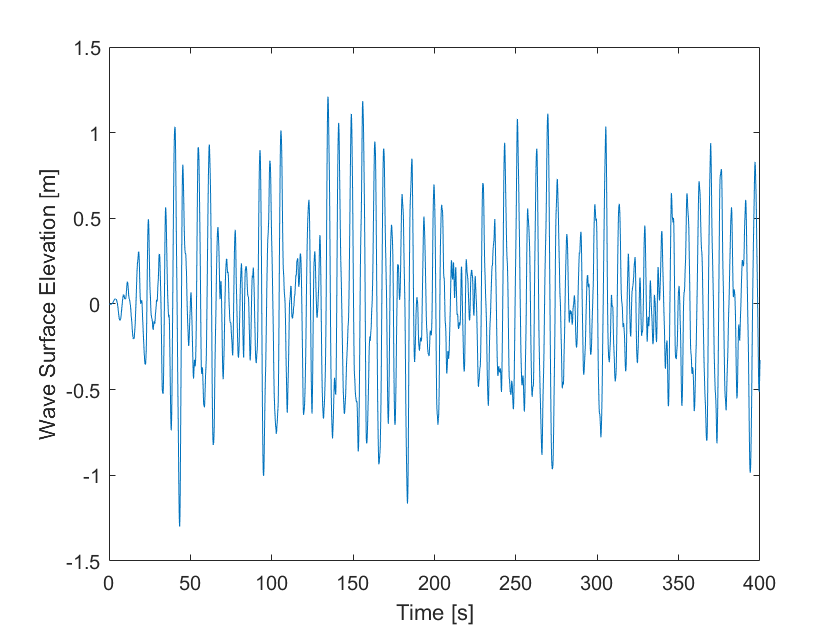

figure;plot(wave_data.time,wave_data.elevation)
xlabel("Time [s]")
ylabel("Wave Surface Elevation [m]")

### **Body Class Data**

Data from WEC-Sim’s [Body Class](http://wec-sim.github.io/WEC-Sim/code_structure.html#body-class) includes information about each body, including the body’s position,  velocity, acceleration, forces acting on the body, and the body’s name.  For the RM3 example there will be 2 boides a float and a spar.

bodies = output.bodies

bodies = 1×2 struct array with fields:
    name
    time
    position
    velocity
    acceleration
    forceTotal
    forceExcitation
    forceRadiationDamping
    forceAddedMass
    forceRestoring
    forceMorrisonAndViscous
    forceLinearDamping


body1 = output.bodies(1)

body1 = struct with fields:
                       name: 'float'
                       time: [40001×1 double]
                   position: [40001×6 double]
                   velocity: [40001×6 double]
               acceleration: [40001×6 double]
                 forceTotal: [40001×6 double]
            forceExcitation: [40001×6 double]
      forceRadiationDamping: [40001×6 double]
             forceAddedMass: [40001×6 double]
             forceRestoring: [40001×6 double]
    forceMorrisonAndViscous: [40001×6 double]
         forceLinearDamping: [40001×6 double]


## 3. Apply MHKiT Wave Module

% Use the MHKiT Wave Module to calculate the wave spectrum from the WEC-Sim Wave Class Data
sample_rate=60

sample_rate = 60

nnft=1000        % Number of bins in the Fast Fourier Transform

nnft = 1000

ws_spectrum = elevation_spectrum(wave_data.elevation, sample_rate, nnft,wave_data.time)

ws_spectrum = struct with fields:
       spectrum: [501×1 double]
           type: 'Spectra from Timeseries'
      frequency: [501×1 double]
    sample_rate: 60
           nnft: 1000


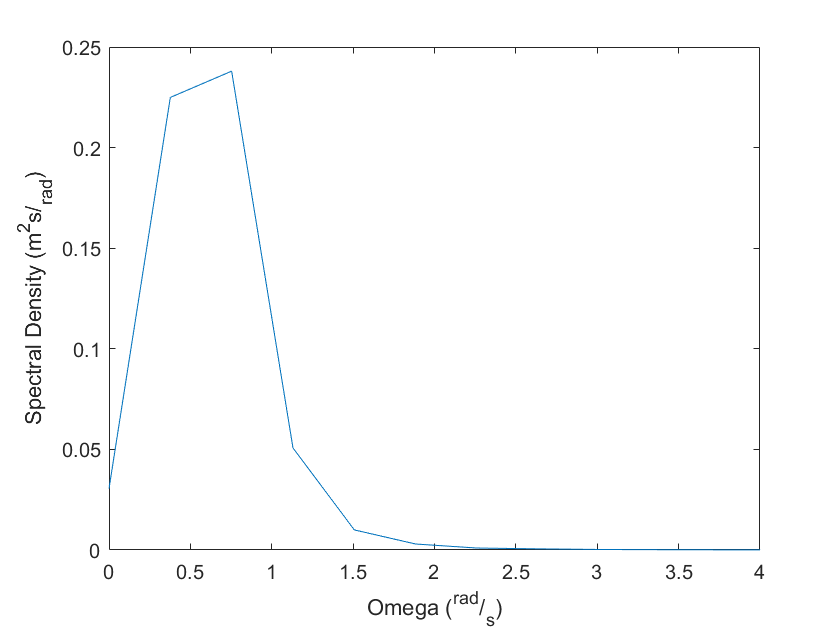

% Plot calculated wave spectrum
spect_plot = plot_spectrum(ws_spectrum);xlim([0, 4]);

% Calculate Peak Wave Period (Tp) and Significant Wave Height (Hm0)
Tp = peak_period(ws_spectrum)

    8.3333



Tp = 8.3333

Hm0 = significant_wave_height(ws_spectrum)

Hm0 = 1.7857